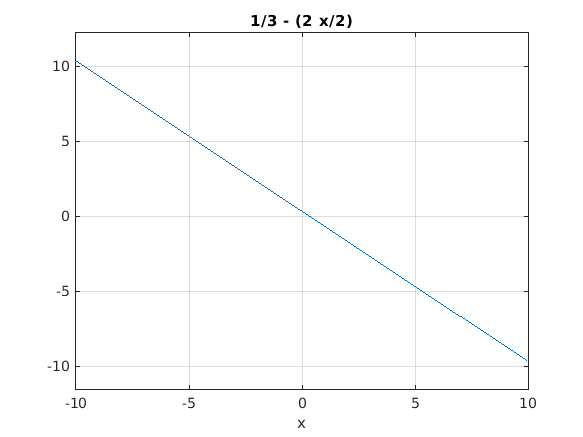

ezplot('1/3 - (2*x/2)' , [ -10,10])
grid

This is the first given code

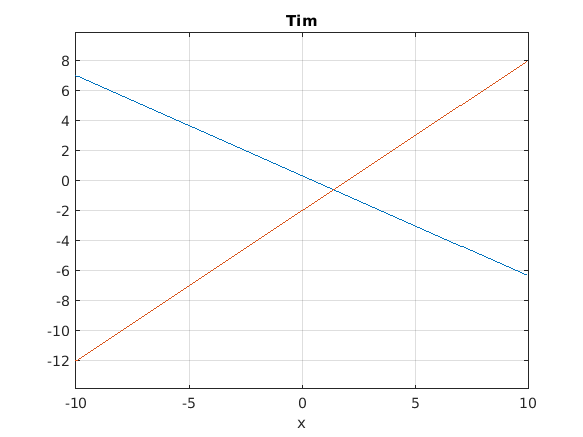

ezplot('1/3 - (2*x/3)' , [ -10,10])
hold on
ezplot('x-2', [-10,10])
title('Tim')
grid 
hold off

Some more complex code that shows intersections.

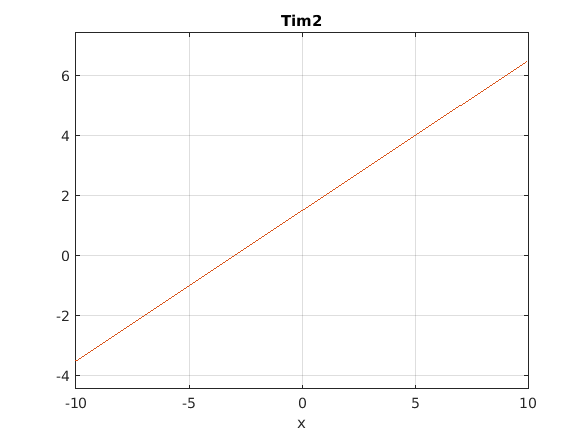

ezplot('(3+x)/2' , [ -10,10])
hold on
ezplot('3/2 + 1/2*x ', [-10,10])
title('Tim2')
grid 
hold off

There are infinitely many solutions because the second equation is the first equation muliplied by -2.  

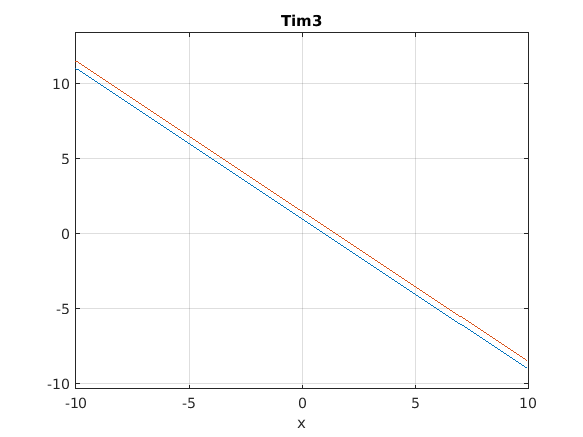

ezplot('1-x' , [ -10,10])
hold on
ezplot('3/2 - x ', [-10,10])
title('Tim3')
grid 
hold off

There are no solutions as the lines are parallel 

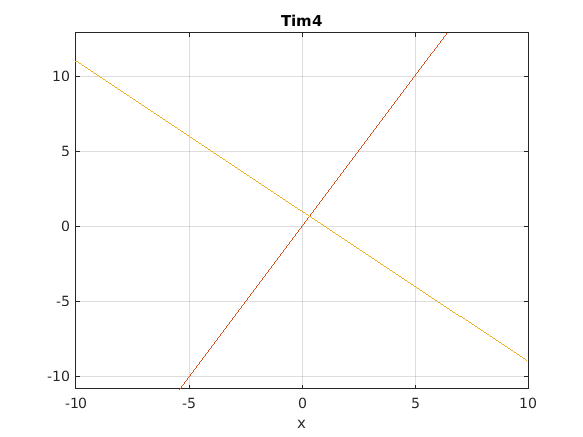

ezplot('1-x' , [ -10,10])
hold on
ezplot('2*x', [-10,10])
hold on
ezplot('1-x', [-10,10])
title('Tim4')
grid 
hold off

There is a unique solution 

Looking at the graph, you can estimate it to be around (1,1)

Here is how you find it exactly:

A = [1 1;
    2 -1;
    -1 -1]

A =      1     1
     2    -1
    -1    -1


b = [1;
     0;
     -1]

b =      1
     0
    -1


 x = A\b

x =     0.3333
    0.6667


 a1 = A(:,1)

a1 =      1
     2
    -1


 a2 = A(:,2)

a2 =      1
    -1
    -1


 
 r1 = a1*(x(1,1))

r1 =     0.3333
    0.6667
   -0.3333


 r2 = a2*(x(2,1))

r2 =     0.6667
   -0.6667
   -0.6667


 
 
 R = []


R =

     []



 
 plot([0,r1(1,1)],[0,r1(2,1)],'b')
 hold on
 r3 = r1 + r2

r3 =     1.0000
    0.0000
   -1.0000


 plot([r1(1,1), r3(1,1)], [r1(2,1),r3(2,1)],'r')
 plot([0,b(1,1)],[0,b(2,1)],'g')

We scale the column space of A by the x vector, giving us r1 and r2. We plot r1 and then add r2 to r1, giving us the vector r3. We then plot r3 and b, and we can see that r1 and r2 create b. We are very smart. Because the 3rd equation is not linearly independent on the first, we remain in the dimension R2.

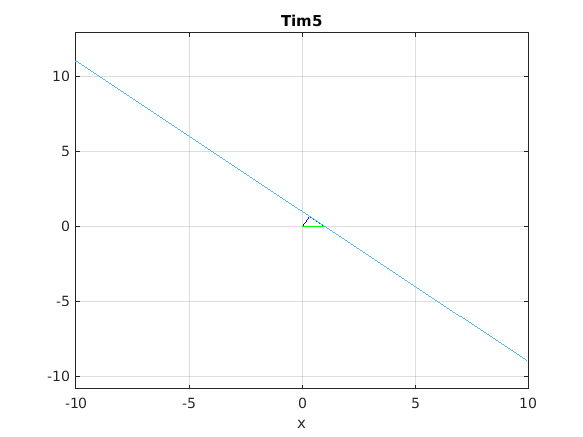

ezplot('1-x' , [ -10,10])
hold on
ezplot('1-x', [-10,10])
hold on
ezplot('1-x', [-10,10])
title('Tim5')
grid 
hold off

There are infinitely many solutions because all 3 equations are linear permutions of y = 1-x

A = [1 -1 2;
     -3 1 1;
      1 4 -6]

A =      1    -1     2
    -3     1     1
     1     4    -6


B = [0.5 0.35 0.15;
     0.35 0.6 0.05;
     0.15 0.05 0.8]

B =     0.5000    0.3500    0.1500
    0.3500    0.6000    0.0500
    0.1500    0.0500    0.8000


 C = [1 -1;
      1 2;
      -3 2]

C =      1    -1
     1     2
    -3     2


  2*3

ans = 6

  A*A

ans =      6     6   -11
    -5     8   -11
   -17   -21    42


  A*B

ans =     0.4500   -0.1500    1.7000
   -1.0000   -0.4000    0.4000
    1.0000    2.4500   -4.4500


  B*A

ans =    -0.4000    0.4500    0.4500
   -1.4000    0.4500    1.0000
    0.8000    3.1000   -4.4500


  A*C

ans =     -6     1
    -5     7
    23    -5


  %C*A This does not work because C has fewer Columns than A has rows
  2*B

ans =     1.0000    0.7000    0.3000
    0.7000    1.2000    0.1000
    0.3000    0.1000    1.6000


C*A does not work because the rows of A are not equal to the columns of C.  A*B does not equal B*A in matrix multiplication. 2*B produces B scaled by 2 which is the respected result.

A'

ans =      1    -3     1
    -1     1     4
     2     1    -6


B'

ans =     0.5000    0.3500    0.1500
    0.3500    0.6000    0.0500
    0.1500    0.0500    0.8000


C'

ans =      1     1    -3
    -1     2     2


C'*A

ans =     -5   -12    21
    -5    11   -12


%A*C'the inverted dimensions are incompatable
(A')'

ans =      1    -1     2
    -3     1     1
     1     4    -6


(A' + A)/2

ans =     1.0000   -2.0000    1.5000
   -2.0000    1.0000    2.5000
    1.5000    2.5000   -6.0000


A*C' does not work because the rows are not equal to the columns of C'.  

C = [1 1 1 1;
     1 2 1 2;
     1 1 1 0;
     1 4 2 3]

C =      1     1     1     1
     1     2     1     2
     1     1     1     0
     1     4     2     3


 'N' - 64

ans = 14

 'O' - 64

ans = 15

 
encode =  C * [14; 15; 15; 14]

encode =     58
    87
    44
   146


D = inv(C)

D =     -1     2     1    -1
    -2     1     1     0
     3    -3    -1     1
     1     0    -1     0


decodeNum = D * [42;51;34;81]

decodeNum =     13
     1
    20
     8


decode = decodeNum + [64;64;64;64]

decode =     77
    65
    84
    72


char(decode)

ans = 4×1 char array
    'M'
    'A'
    'T'
    'H'
